Flint Morgan HW 4

- Kernel Ridge Regression

a)

rand('state',0);
randn('state',0);
n = 100;
x = rand(1,n); % training inputs
y = sin(9*x) + sqrt(1/3)*randn(1,n); % training outputs
t = linspace(0,1,1001); % test inputs

K = (x.*x'+1).^4;
f = y*((K+ eye(n))\K);

mse = norm(f-y)^2/n

mse = 0.4594

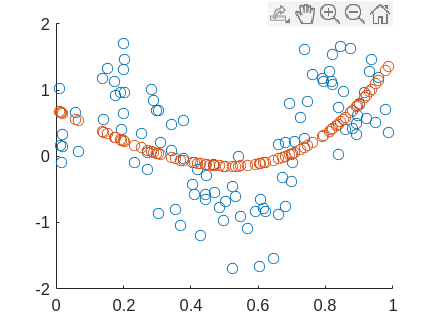


figure
hold on
scatter(x,y)
scatter(x,f)

b)

min_mse = 1000;

for bandwidth = 0.01:0.01:10
K = exp(-((x.*x')^2)/(2*bandwidth^2));
f = y*((K+ eye(n))\K);

mse = norm(f-y)^2/n;
if mse < min_mse
    min_mse = mse;
    min_band = bandwidth;
    min_f = f;
end
end
min_mse

min_mse = 0.5689

min_band

min_band = 2.8800

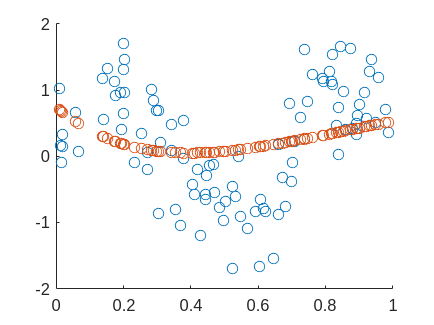

figure
hold on
scatter(x,y)
scatter(x,min_f)

2. SVM

clear;
load('/home/flint/Desktop/2023-Fall/machine learning independent study/Hw04/hw04_files/mnist_49_3000.mat');
train_x = x(:,1:2000);
train_y = y(1,1:2000);
test_x = x(:,2001:end);
test_y = y(:,2001:end);

p = 1;
k = (x'*x+1).^p;
f = smo(k,y,1,0.001);

mse = norm(f-y)^2/length(y)

mse = 1.0058